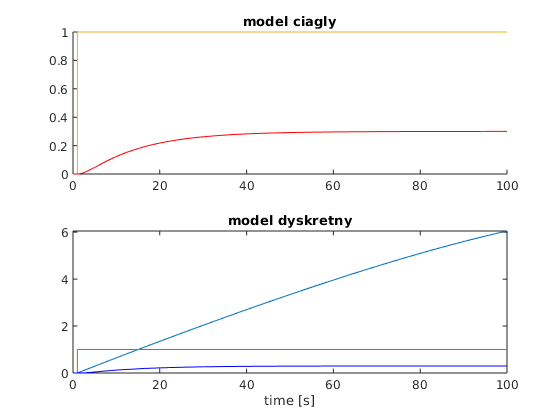

subplot(2,1,1)
hold on
plot(out.step)
plot(out.model_ciagly, 'r')
title('model ciagly')
hold off
subplot(2,1,2)
hold on
plot(out.step)
plot(out.model_dyskretny, 'b')
xlabel('time [s]')
title('model dyskretny')
hold off

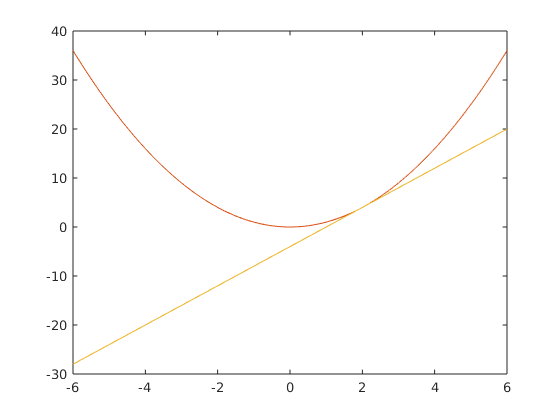


u = linspace(-4,4);
u_ = 0;
y_t= K * ((u .* a1) + (u.^2 .*a2) + (u.^3 .*a3) + (u.^4 .*a4));

y_lin = @(u) K*(u-u_)*(2*a2*u_ + 3*a3*u_^2 + 4*a4*u_^3) + K*(a2*u_^2 + a3*u_^3 + a4*u_^4) + K*a1*u;
figure;
subplot(3,1,1)
hold on
plot(u, y_t)
plot(u, y_lin(u))
hold off
title('u__ =0')
xlabel('u');
ylabel('y(u)');
%%%%%%%%%%%%%%
subplot(3,1,2)
u_ = 1;
hold on
plot(u, y_t)
plot(u, y_lin(u))
hold off
title('u__ =1')
xlabel('u');
ylabel('y(u)');

x = linspace(-6,6,1000);
figure;
plot(x, x.^2)
x_ = 2;
hold on
u_non_linear = x.^2;
plot(x, u_non_linear)
u_linear = x_^2 + 2*x_*(x-x_);
plot(x, u_linear);
hold off


plot(x, (u_linear-u_non_linear).^2)
